8.2

(1)

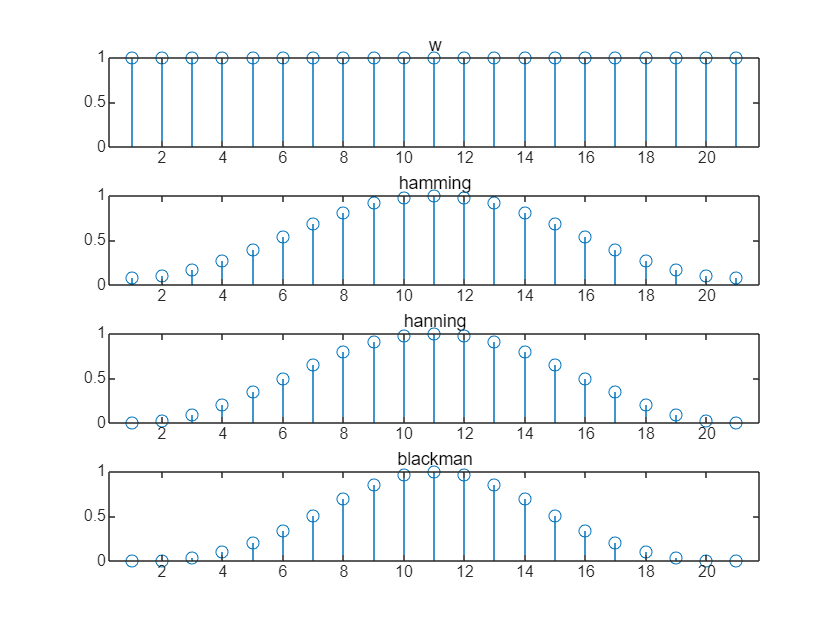

N = 21;
w = ones(1,N);
w_hamming = hamming(N);
w_hanning = hann(N);
w_blackman = blackman(N);
figure
subplot(411),
stem(w),title('w')
subplot(412),
stem(w_hamming),title('hamming')
subplot(413),
stem(w_hanning),title('hanning')
subplot(414),
stem(w_blackman),title('blackman')

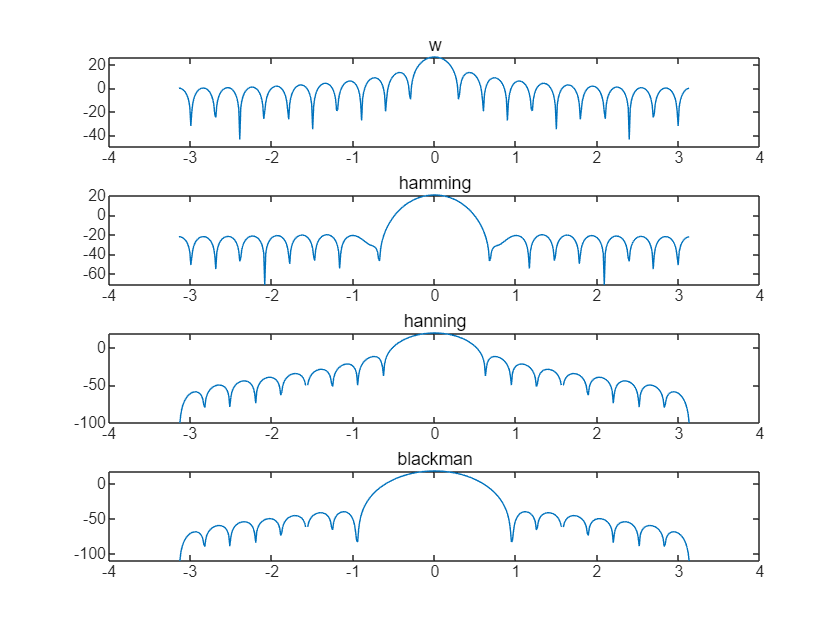


[W,omega]= DTFT(w,512);
[W_hamming,omega_ham]= DTFT(w_hamming,512);
[W_hanning,omega_han] = DTFT(w_hanning,512);
[W_blackman,omega_black] = DTFT(w_blackman,512);
figure
subplot(411),
plot(omega,20*log10(abs(W))),title('w')
subplot(412),
plot(omega_ham,20*log10(abs(W_hamming))),title('hamming')
subplot(413),
plot(omega_han,20*log10(abs(W_hanning))),title('hanning')
subplot(414),
plot(omega_black,20*log10(abs(W_blackman))),title('blackman')

（2）

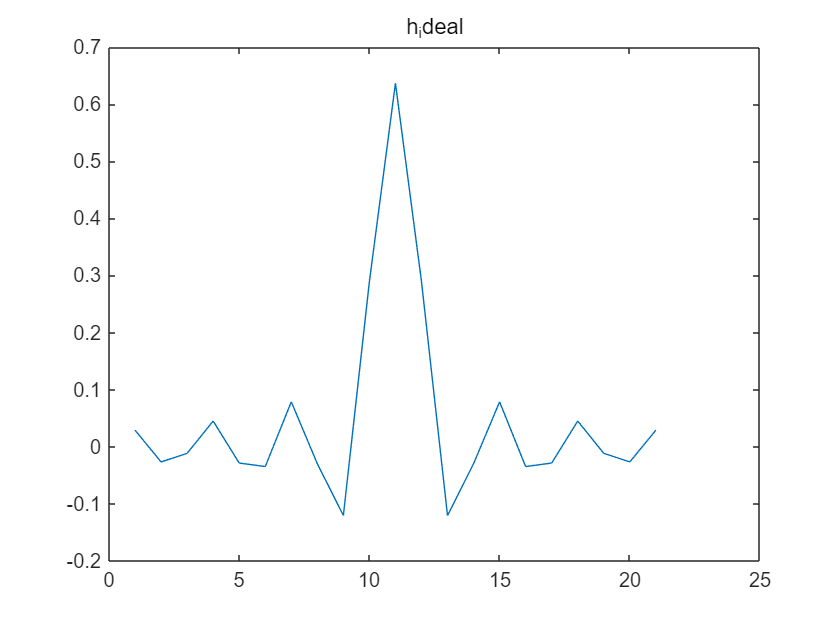

clear
N = 21;
w=hamming(N);
wc= 2.0;
n=0:20;
h_ideal=LPFtrunc(N);

h = w'.*h_ideal;
[H,omega]= DTFT(h,512);

figure
plot(h_ideal),title('h_ideal')

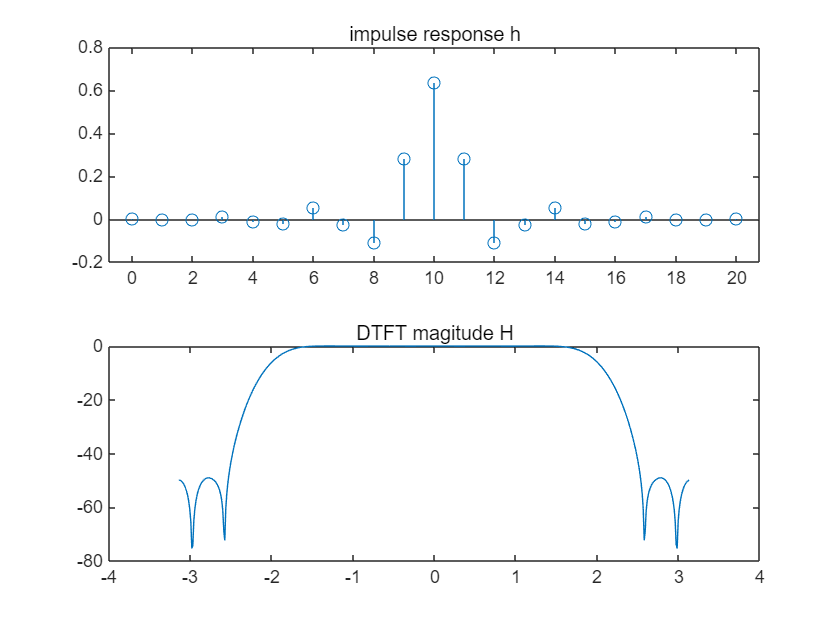


figure
subplot(211),
stem(n,h),title('impulse response h')
subplot(212),
plot(omega,20*log10(abs(H))),title('DTFT magitude H')

8.3

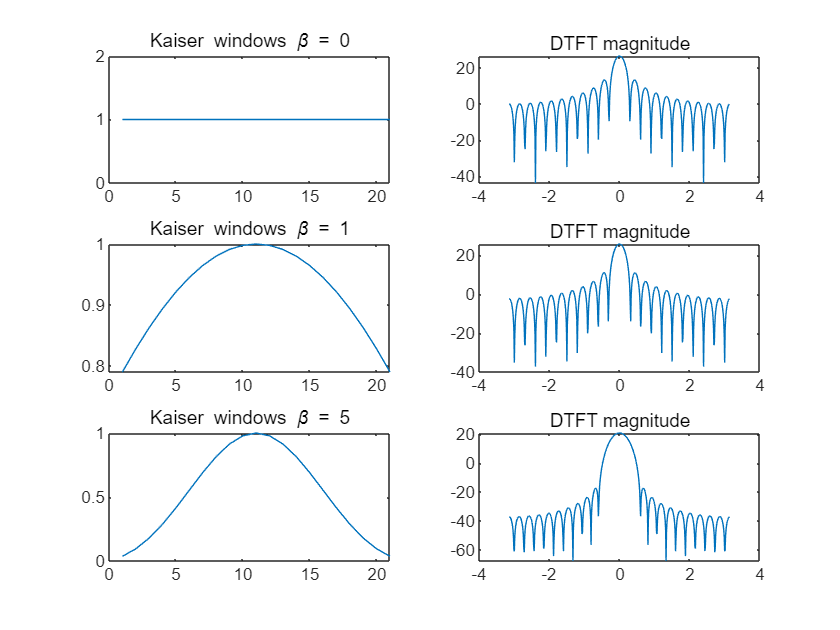

clear;
N = 21;
beta = [0 1 5];
win1 = kaiser(N,beta(1));
win2 = kaiser(N,beta(2));
win3 = kaiser(N,beta(3));

[Win1,w1] = DTFT(win1,512);
[Win2,w2] = DTFT(win2,512);
[Win3,w3] = DTFT(win3,512);

figure
subplot(321)
plot(win1),title('Kaiser windows \beta = 0')
subplot(322)
plot(w1,20*log10(abs(Win1))),title('DTFT magnitude')

subplot(323)
plot(win2),title('Kaiser windows \beta = 1')
subplot(324)
plot(w2,20*log10(abs(Win2))),title('DTFT magnitude')

subplot(325)
plot(win3),title('Kaiser windows \beta = 5')
subplot(326)
plot(w3,20*log10(abs(Win3))),title('DTFT magnitude')

（2）

clear
load nspeech2.mat
ws = 2.2;
wp = 1.8;
delta_p =0.05;
delta_s =0.005;
delta = delta_s;
A =-20*log10(delta)

A = 46.0206

beta = 0.5842*(A-21)^(0.4) + 0.07886*(A-21);
N=ceil(1+(A-8)/(2.285*(ws-wp)))

N = 43

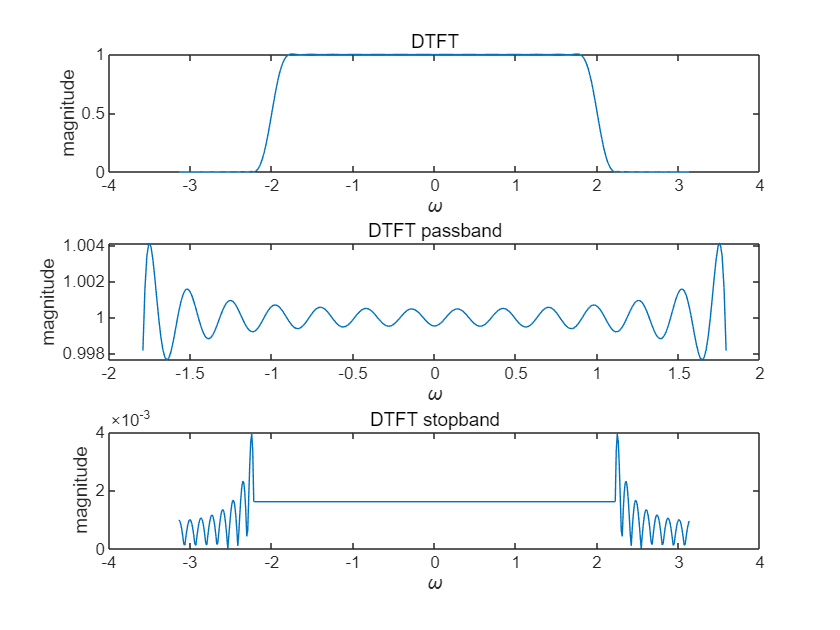


win_ka = kaiser(N,beta);
h_ideal=LPFtrunc(N);
h = win_ka'.*h_ideal;
[H,w]= DTFT(h,512);

figure;
subplot(311);
plot(w,abs(H));
xlabel("\omega");ylabel("magnitude");title('DTFT');
subplot(312);
plot(w(abs(w)<=1.8),abs(H(abs(w)<=1.8)));
xlabel("\omega");ylabel("magnitude");title('DTFT passband');
subplot(313);
plot(w(abs(w)>=2.2),abs(H(abs(w)>=2.2)));
xlabel("\omega");ylabel("magnitude");title('DTFT stopband');

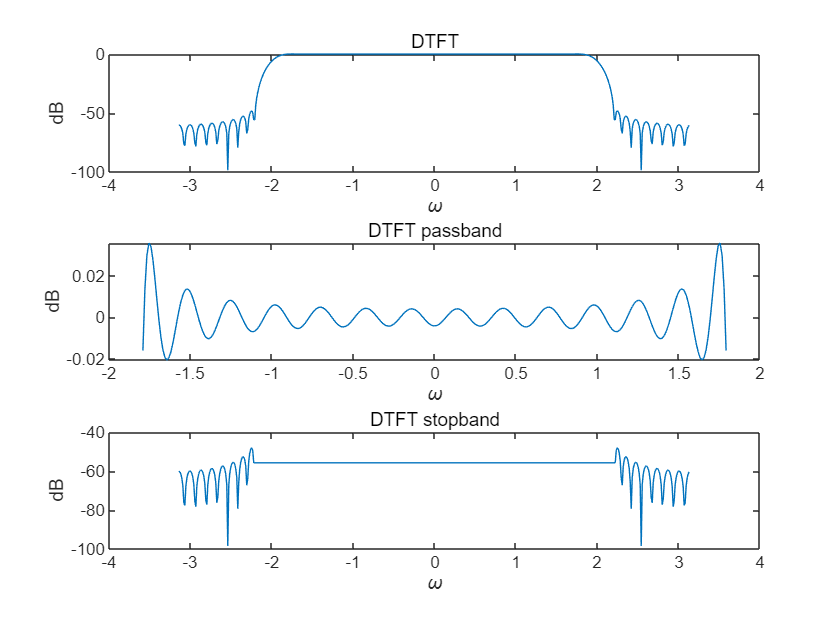



figure;
subplot(311);
plot(w,20*log10(abs(H)));
xlabel("\omega");ylabel("dB");title('DTFT');
subplot(312);
plot(w(abs(w)<=1.8),20*log10(abs(H(abs(w)<=1.8))));
xlabel("\omega");ylabel("dB");title('DTFT passband');
subplot(313);
plot(w(abs(w)>=2.2),20*log10(abs(H(abs(w)>=2.2))));
xlabel("\omega");ylabel("dB");title('DTFT stopband');

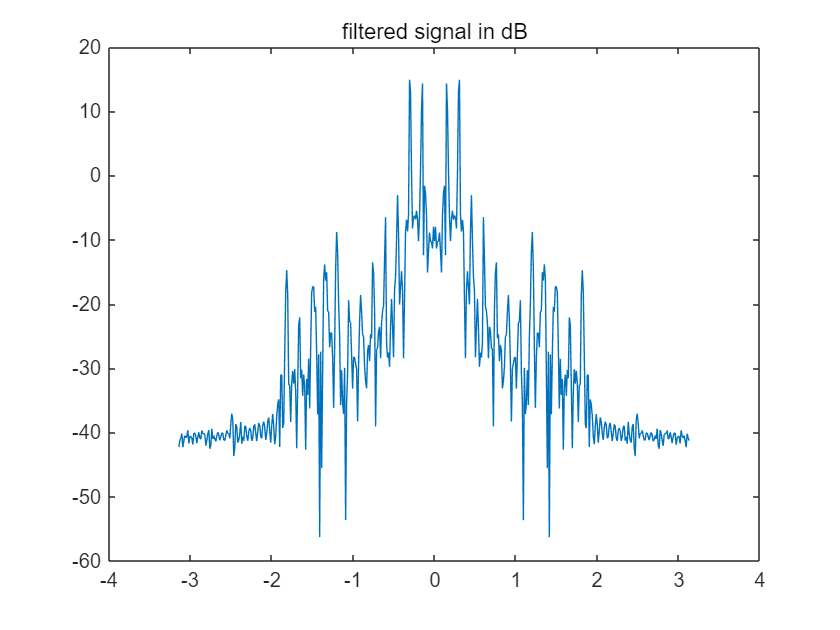


y_fil = conv(h,nspeech2');
[Y_fil,w_fil] = DTFT(y_fil(20001:20401),0);
figure;
plot(w_fil,20*log10(abs(Y_fil))); 
title('filtered signal in dB');


sound(nspeech2)


%delta = 0.004

8.4

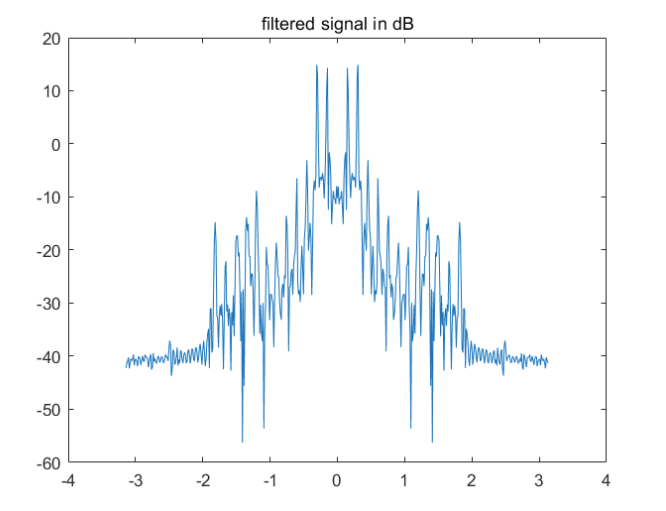

clear
load nspeech2.mat

wp = 1.8;
ws = 2.2;
wc = 2.0;
delta_p = 0.05;
delta_s = 0.005;

f = [wp,ws];
m = [1, 0];
ripple = [delta_p, delta_s];
[n,fo,mo,w] = firpmord(f,m,ripple,2*pi);

b = firpm(n, fo, mo, w);
N=length(b)

N = 26

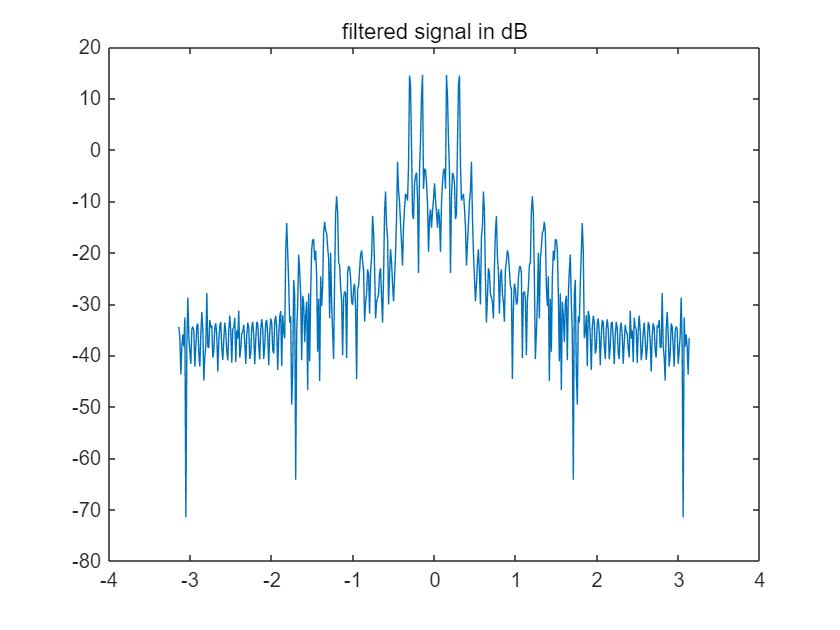


y_fil = conv(b,nspeech2');
[Y_fil,w_fil] = DTFT(y_fil(20001:20401),0);
figure;
plot(w_fil,20*log10(abs(Y_fil))); 
title('filtered signal in dB');


%sound(nspeech2)
sound(y_fil)